# UR5e Control for RoboCup ARM Challenge

## Códigos generados de la información de MATLAB

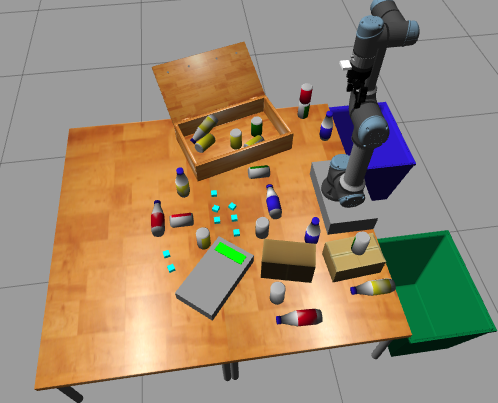

## Conectando Matlab y Gazebo

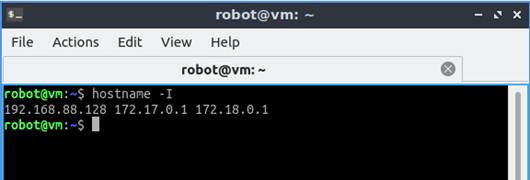

rosIP = '172.18.0.1';
[jointSub,trajGoal,trajAct,gripGoal,gripAct,rgbImgSub,rgbDptSub] = IniciarRobot(rosIP);

Shutting down global node /matlab_global_node_24016 with NodeURI http://PCIrandi:33501/ and MasterURI http://172.18.0.1:11311.
Initializing global node /matlab_global_node_91901 with NodeURI http://PCIrandi:36239/ and MasterURI http://172.18.0.1:11311.
/camera/depth/camera_info                                  
/camera/depth/image_raw                                    
/camera/depth/points                                       
/camera/parameter_descriptions                             
/camera/parameter_updates                                  
/camera/rgb/camera_info                                    
/camera/rgb/image_raw                                      
/clock                                                     
/ft_sensor/raw                                             
/gazebo/link_states                                        
/gazebo/model_states                                       
/gazebo/parameter_descriptions                             
/gazebo/parameter_updates  

%jointSub : Receive current robot configuration
%trajGoal : Paquete que contiene información de movimiento articular deseado
%trajAct  : Cliente que recibe el trajGoal
%gripGoal : Paquete que contiene información de movimiento del gripper
%gripAct  : Cliente que recibe el gripGoal
%rgbImgSub: Recibe la información de la cámara RGB
%rgbDptSub: Recibe la información de la cámara de profundidad

## Leyendo los valores articulares

ValoresArticulares = LeerValoresArticulares(jointSub)

ValoresArticulares = struct with fields:
         q1: 0.0021
         q2: -0.0024
         q3: 4.3409e-05
         q4: 0.0056
         q5: 0.0040
         q6: -7.5744e-04
    Gripper: 2.0850e-05


%ValoresArticulares : Recibe las 6 coordenadas articulares y el valor del

## Abriendo y cerrando el gripper

ValorGripper = 0.0;    %0 abierto/desactivado 0.8 cerrado/activado
ActivacionGripper(ValorGripper,gripAct,gripGoal,jointSub);
%Función que abre y cierra el gripper, para que esta función se itere hasta
%que culmine la acciòn deberá entrar al código y descomentar la sección
%correspondiente

## Moviendo el robot a nivel articular

q =zeros(6,1);
q(1) =0;
q(2) =-0.9;
q(3) =0;
q(4) =0;
q(5) =0;
q(6) =0;

MoverRobot(q,trajAct,trajGoal,jointSub);
%Función que mueve las articulaciones del robot, para que esta función se itere hasta
%que culmine la acción deberá entrar al código y descomentar la sección
%correspondiente

## Cinemática inversa usando la funcion de inverseKinematics de Matlab

UR5e = loadrobot('universalUR5e')

UR5e =   rigidBodyTree with properties:

     NumBodies: 10
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'base'  'base_link_inertia'  'shoulder_link'  'upper_arm_link'  'forearm_link'  'wrist_1_link'  'wrist_2_link'  'wrist_3_link'  'flange'  'tool0'}
      BaseName: 'base_link'
       Gravity: [0 0 0]
    DataFormat: 'struct'


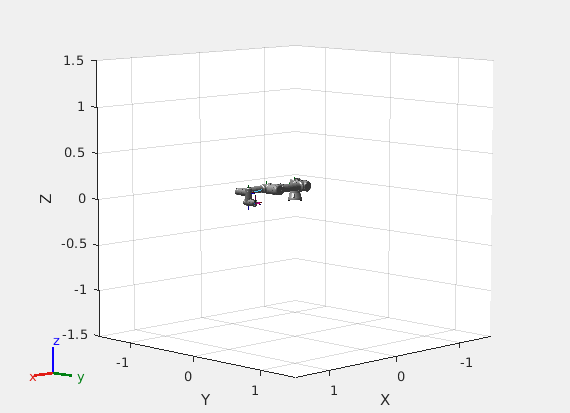

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


configSoln = homeConfiguration(UR5e);
show(UR5e,configSoln)


% Ajuste de la transformación de cuerpos de la versión previa del robot
% tform=UR5e.Bodies{3}.Joint.JointToParentTransform;
% UR5e.Bodies{3}.Joint.setFixedTransform(tform*eul2tform([pi/2,0,0]));
tform=UR5e.Bodies{4}.Joint.JointToParentTransform;
UR5e.Bodies{4}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));
tform=UR5e.Bodies{7}.Joint.JointToParentTransform;
UR5e.Bodies{7}.Joint.setFixedTransform(tform*eul2tform([-pi/2,0,0]));

%
ik = inverseKinematics("RigidBodyTree",UR5e); % Create Inverse kinematics solver

ikWeights = [0.25 0.25 0.25 0.1 0.1 .1]; % configuration weights for IK solver [Translation Orientation] see documentation
jointStateMsg = receive(jointSub,3) % receive current robot configuration

jointStateMsg = struct with fields:
    MessageType: 'sensor_msgs/JointState'
         Header: [1×1 struct]
           Name: {7×1 cell}
       Position: [7×1 double]
       Velocity: [7×1 double]
         Effort: [7×1 double]


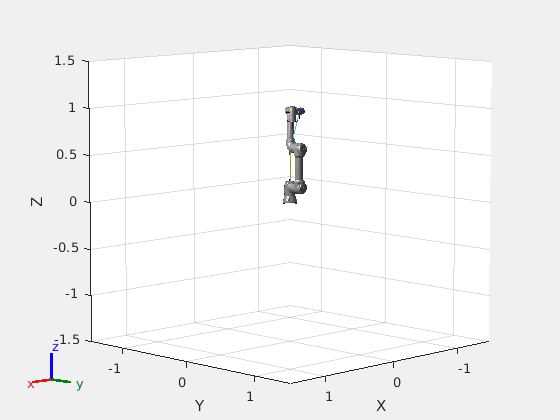

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



configSoln(1).JointPosition = jointStateMsg.Position(4); % update configuration in initial guess
configSoln(2).JointPosition = jointStateMsg.Position(3);
configSoln(3).JointPosition = jointStateMsg.Position(1);
configSoln(4).JointPosition = jointStateMsg.Position(5);
configSoln(5).JointPosition = jointStateMsg.Position(6);
configSoln(6).JointPosition = jointStateMsg.Position(7);
figure
show(UR5e,configSoln)

### Posición de tool0.

Busquemos una posición del gripper que sea correcta. Probemos (x, y, z)=(0, 0.31, 0.42)

gripperX = -0.02;
gripperY = 0.31;
gripperZ = 0.51;

gripperTranslation = [gripperX gripperY gripperZ];
gripperRotation = [-pi/2 -pi 0]; %  [Z Y X]radians


tform = eul2tform(gripperRotation); %
tform(1:3,4) = gripperTranslation'; % set translation in homogeneous transform

[configSoln, solnInfo] =ik('tool0',tform,ikWeights,configSoln)

configSoln = 1×6 struct array with fields:
    JointName
    JointPosition


solnInfo = struct with fields:
           Iterations: 35
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9024e-09
             ExitFlag: 1
               Status: 'success'


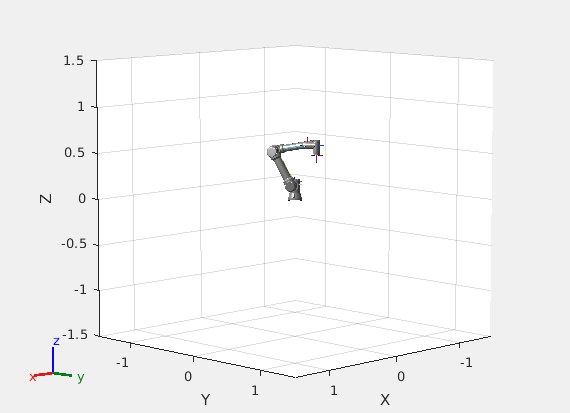

ans =   Axes (Primary) with properties:

             XLim: [-1.5000 1.5000]
             YLim: [-1.5000 1.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties



show(UR5e,configSoln)


q = zeros(6,1);
for n = 1:6
    q(n) = configSoln(n).JointPosition;
end
q = mod(q-pi,2*pi)-pi

q =    -1.0629
    0.5012
   -1.8812
   -1.7616
    3.1416
   -1.0629


MoverRobot(q,trajAct,trajGoal,jointSub);

## Cinemática inversa usando la solución exacta.

## Receive Camera Image Using ROS Subscriber

curImage = receive(rgbImgSub,3)
rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
imshow(rgbImg)

## Receive Depth Image Using ROS Subscriber

rgbDptSub = rossubscriber('/camera/depth/image_raw',"sensor_msgs/Image","DataFormat","struct");
pause(1)
curDepth = receive(rgbDptSub,3);
depthImg = rosReadImage(rgbDptSub.LatestMessage); 
imshow(depthImg)

### Appendix - Utilities

This section contains two functions that can be reused for packing the goal information for the ROS action goals to the appropriate message structures.